clear
clc
format longg
% Set defaults of graphs and axes
set(groot,'defaultAxesXGrid','on')
set(groot,'defaultAxesYGrid','on')
set(groot,'defaultAxesZGrid','on')
set(groot,'defaultLineLineWidth',2)
set(groot,'defaultLineColor','b')
set(groot,'defaultAxesGridAlpha',0.5);
set(groot,'defaultAxesGridColor',[0.65 0.65 0.65]);
set(groot,'defaultAxesLayer','top');
set(groot,'defaultAxesXMinorGrid','on','defaultAxesXMinorGridMode','manual');

list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end


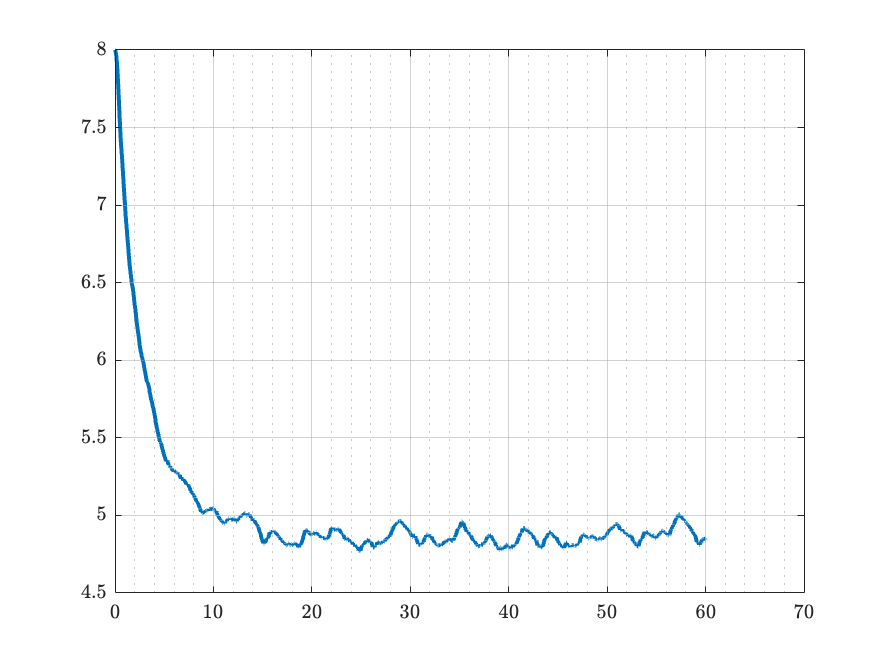

RLdf = readtable("data/RL-ModelB_V1_1,position_sigma_0_25,attitude_sigma_0_62832,run_1-2000000.csv",'PreserveVariableNames',true);
% df = df(:, [1,5])

t = table2array(RLdf(:,2));
z = table2array(RLdf(:,5));
z = z*-1;

plot(t, z)


s1 = stepinfo(z,t, 5,8, 'SettlingTimeThreshold', 0.08)

s1 = struct with fields:
         RiseTime: 5.39505911370009
    TransientTime: 6.67184064573636
     SettlingTime: 6.67184064573636
      SettlingMin: 4.7707586
      SettlingMax: 5.2981057
        Overshoot: 7.64138000000001
       Undershoot: 0
             Peak: 3.2292414
         PeakTime: 24.88



u = [8; 5* ones(size(z,1)-1,1)]

u =      8
     5
     5
     5
     5
     5
     5
     5
     5
     5




data_obj = iddata(z,u,[],'SamplingInstants', t)

data_obj =

Time domain data set with 6002 samples.
Sample time: 0.01 seconds               
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        



sys = tfest(data_obj, 2, 0)

sys =
  From input "u1" to output "y1":
           7.338e04
  ---------------------------
  s^2 + 2.207e05 s + 7.538e04
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "data_obj".
Fit to estimation data: 88.88%                       
FPE: 0.002629, MSE: 0.002625                         
 
Model Properties


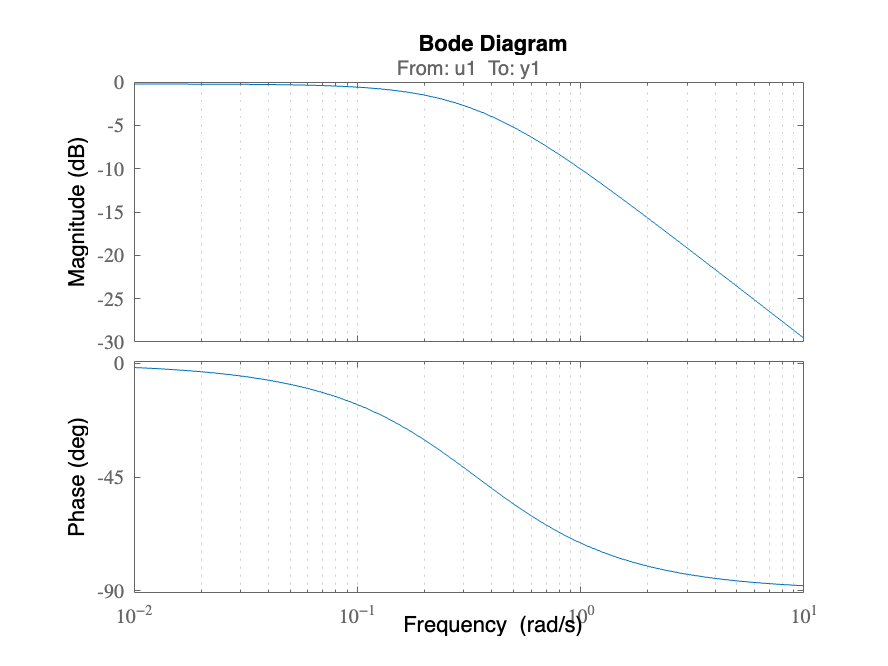


bode(sys)

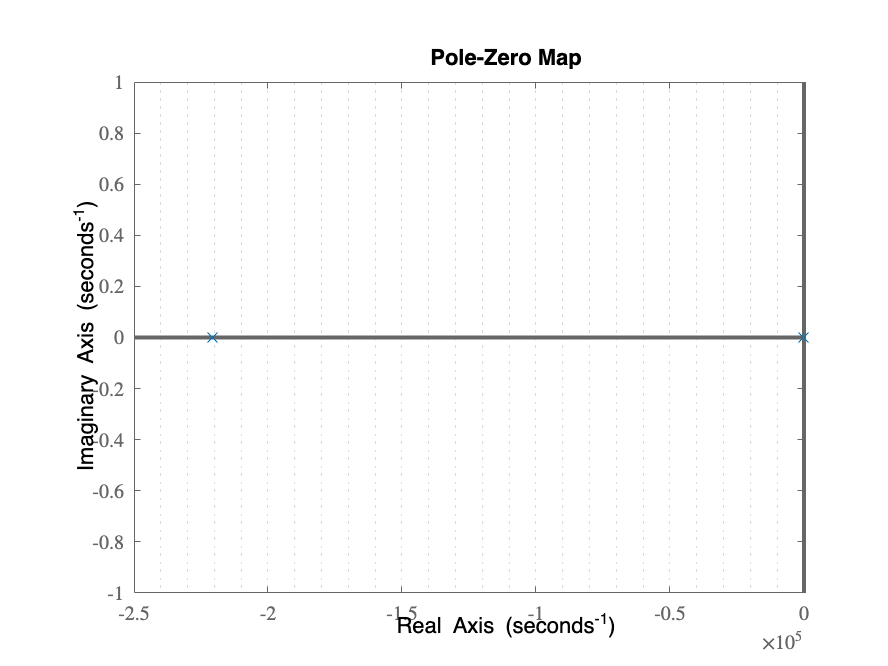

pzmap(sys)

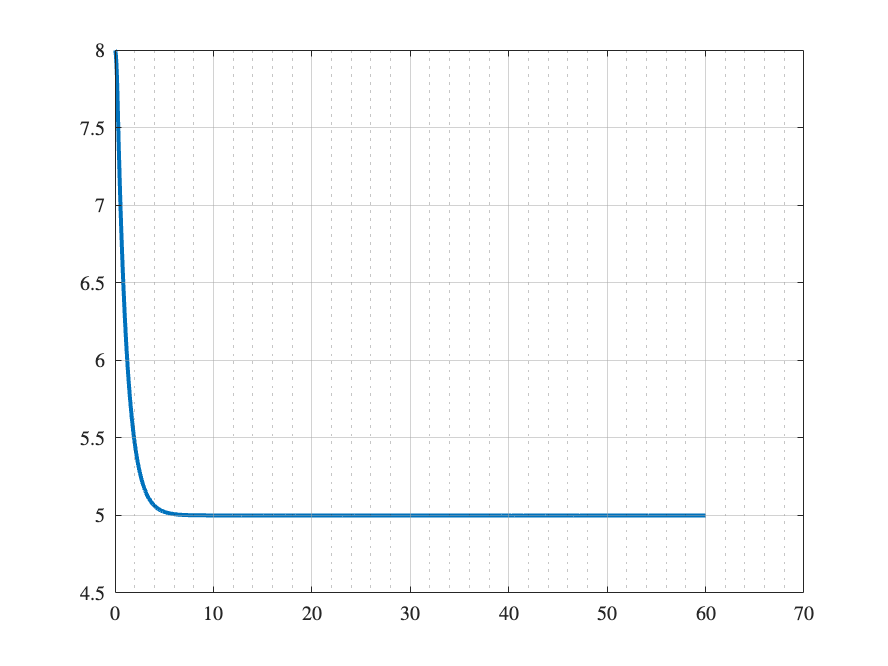

PIDdf = readtable("data/PID-ModelB_V1_1.csv",'PreserveVariableNames',true);
% df = df(:, [1,5])

t = table2array(PIDdf(:,2));
z = table2array(PIDdf(:,5));
z = z*-1;

plot(t, z)


s2 = stepinfo(z,t, 5,8, 'SettlingTimeThreshold', 0.05)

s2 = struct with fields:
         RiseTime: 2.18694815670258
    TransientTime: 3.13140883046849
     SettlingTime: 3.13140883046849
      SettlingMin: 4.9998674
      SettlingMax: 5.2975492
        Overshoot: 0.00441999999998277
       Undershoot: 0
             Peak: 3.0001326
         PeakTime: 28.5



u = [8; 5* ones(size(z,1)-1,1)];


data_obj = iddata(z,u,[],'SamplingInstants', t)

data_obj =

Time domain data set with 6002 samples.
Sample time: 0.01 seconds               
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        



sys = tfest(data_obj, 2, 0)

sys =
  From input "u1" to output "y1":
          1.666
  ---------------------
  s^2 + 2.593 s + 1.666
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "data_obj".
Fit to estimation data: 97.17%                       
FPE: 7.518e-05, MSE: 7.505e-05                       
 
Model Properties


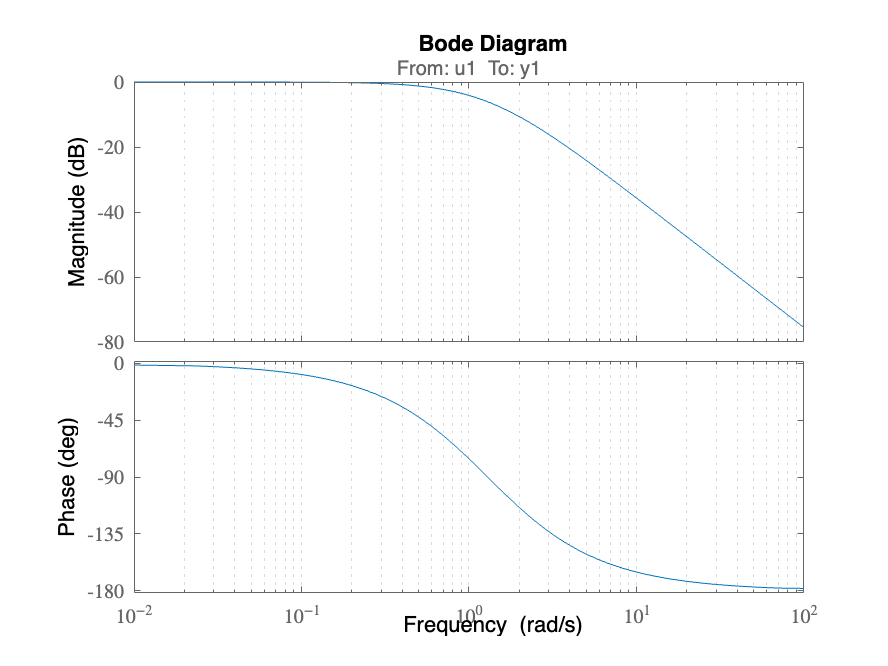


bode(sys)

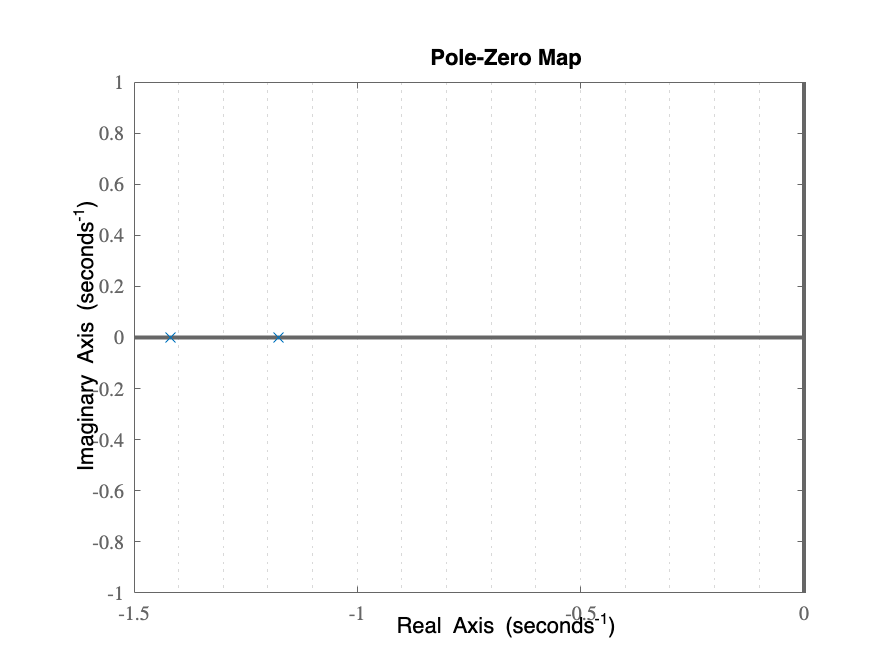

pzmap(sys)

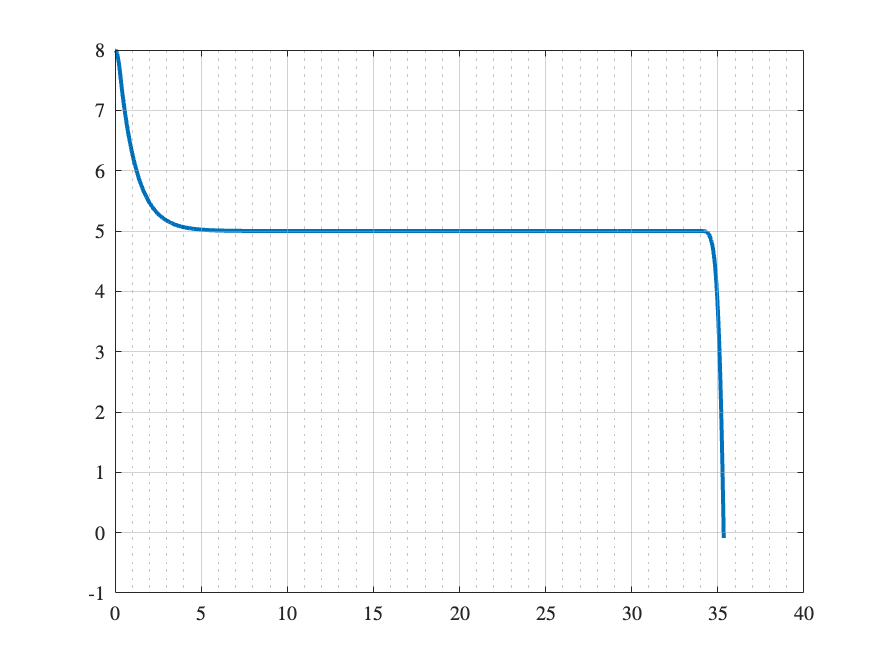

PID_C5df = readtable("../../../caseStudy/data/PID-ModelB_V3_1-Case5.csv",'PreserveVariableNames',true);
% df = df(:, [1,5])

t = table2array(PID_C5df(:,2));
z = table2array(PID_C5df(:,5));
z = z*-1;

plot(t, z)


s3 = stepinfo(z,t, 5,8, 'SettlingTimeThreshold', 0.05)

s3 = struct with fields:
         RiseTime: 2.18826158084342
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: -0.08818999
      SettlingMax: 5.2998805
        Overshoot: 169.606333
       Undershoot: 0
             Peak: 8.08818999
         PeakTime: 35.34



u = [8; 5* ones(size(z,1)-1,1)];


data_obj = iddata(z,u,[],'SamplingInstants', t);

data_obj =

Time domain data set with 3535 samples.
Sample time: 0.01 seconds               
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        



sys = tfest(data_obj, 2, 0)

sys =
  From input "u1" to output "y1":
          2.32
  ---------------------
  s^2 + 3.316 s + 2.337
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "data_obj".
Fit to estimation data: 38.59%                       
FPE: 0.09949, MSE: 0.09921                           
 
Model Properties


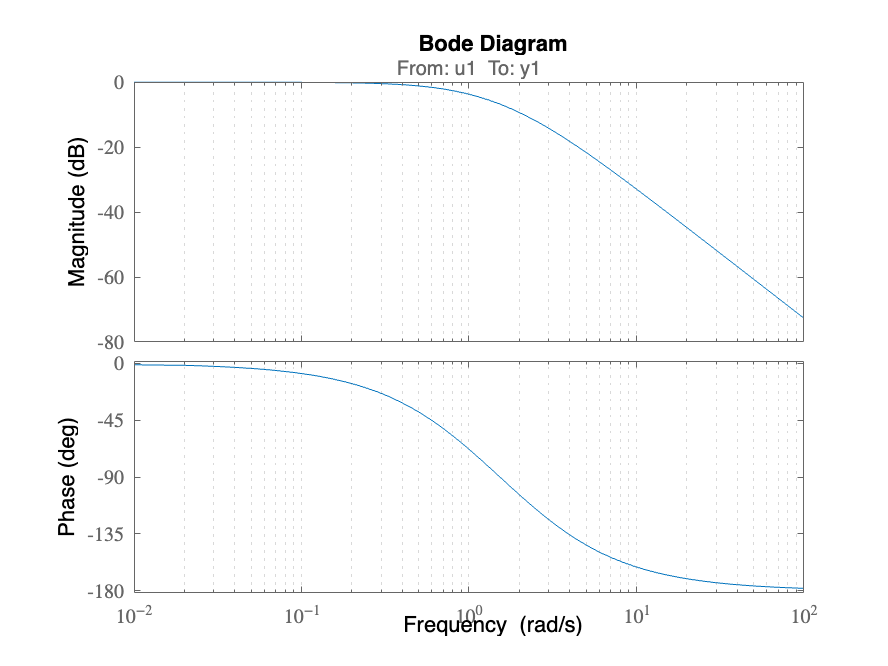


bode(sys)

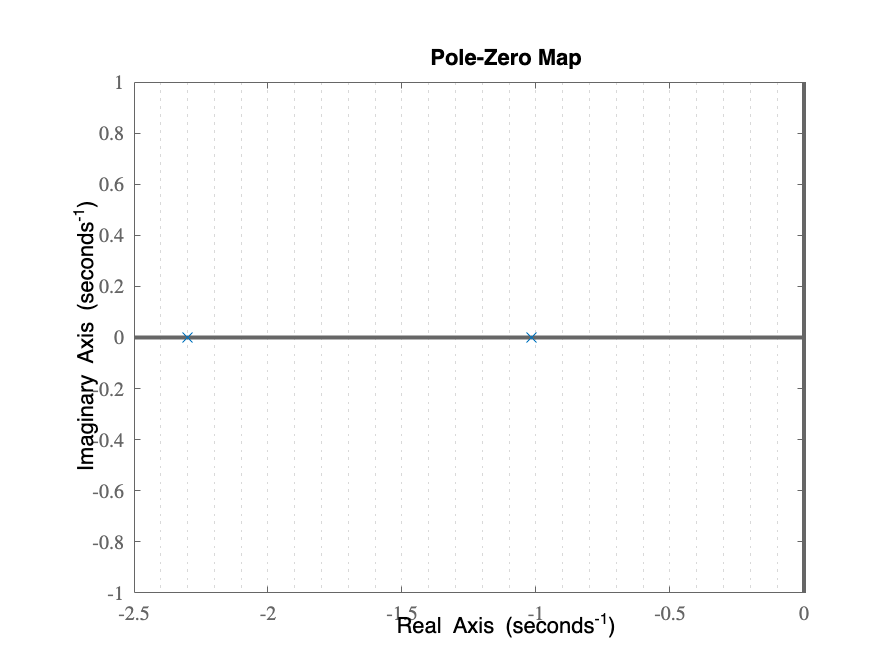

pzmap(sys)

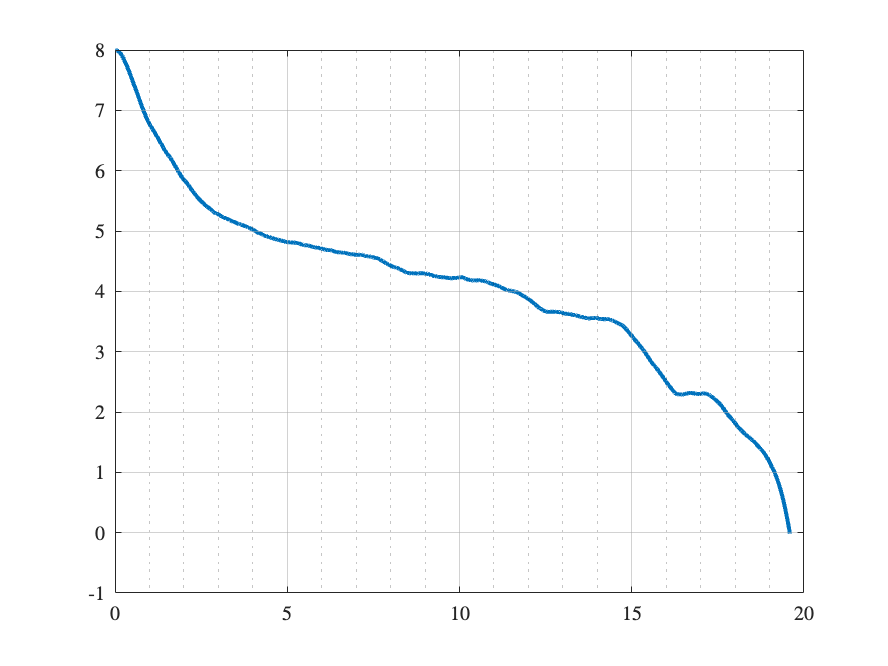

PID_C5df = readtable("../../../caseStudy/data/RL-ModelB_V1_1,position_sigma_0_25,attitude_sigma_0_62832,run_1-2000000-Case5-ftilde_0_63.csv",'PreserveVariableNames',true);
% df = df(:, [1,5])

t = table2array(PID_C5df(:,2));
z = table2array(PID_C5df(:,5));
z = z*-1;

plot(t, z)


s4 = stepinfo(z,t, 5,8, 'SettlingTimeThreshold', 0.05)

s4 = struct with fields:
         RiseTime: 2.5276138527425
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: -0.015707688
      SettlingMax: 5.2991085
        Overshoot: 167.190256266667
       Undershoot: 0
             Peak: 8.015707688
         PeakTime: 19.59



u = [8; 5* ones(size(z,1)-1,1)];


data_obj = iddata(z,u,[],'SamplingInstants', t);

sys = tfest(data_obj, 2, 0)

sys =
  From input "u1" to output "y1":
          46.8
  ---------------------
  s^2 + 443.1 s + 74.81
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "data_obj".
Fit to estimation data: 49.68%                       
FPE: 0.5769, MSE: 0.574                              
 
Model Properties


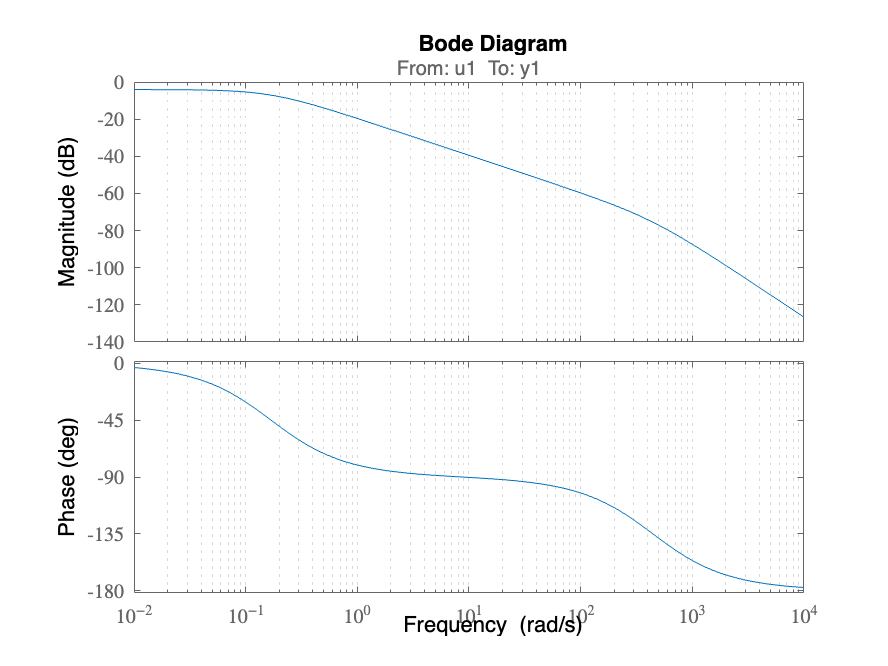


bode(sys)

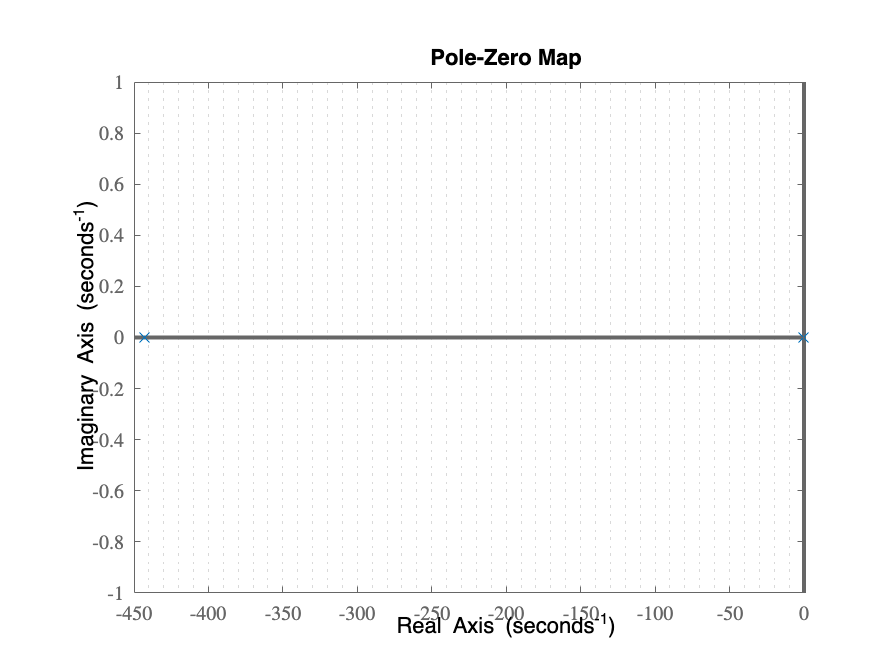

pzmap(sys)